# In-Class Exercises for the Multi-Path Fading

These problems are part of the multi-path fading lecture. You can complete each problem after the corresponding section in the class.

For each problem, complete the sections labeled TODO. 

## Problem 1:  Plotting a Frequency Response of a Delay Channel

Consider a system with the following parameters

bw = 20e6;    % bandwdith
pl = 80;      % path loss (dB)
tau = 200e-9;    % timing error

Plot the real component of the frequency response at 1024 points over the bandwidth.  Assume phase = 0 at DC.  Use 1024 frequency points

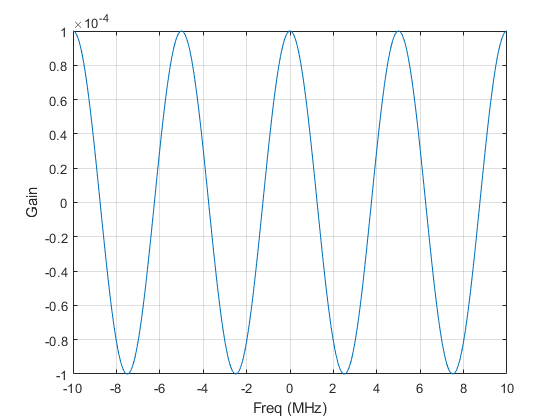

% TODO:  

% We first compute the gain.  Note the amplitude gain is
% the sqrt of the power gain
A = 10.^(-0.05*pl);  % = sqrt( 10^(-0.1*pl))

% Plot 
f = linspace(-bw/2, bw/2, 1024)';
Hreal = A*cos(2*pi*f*tau);
plot(f/1e6, Hreal);
grid on;
xlabel('Freq (MHz)');
ylabel('Gain');

## Problem 2:  Plotting the Channel Response from Frequency Error

Suppose a link has the following parameters:

fc = 37e9;  % carrier freq 
loppm = 1;  % LO error in ppm

Plot the relative change of the gain:

as a function of tau from 0 to 5 us.

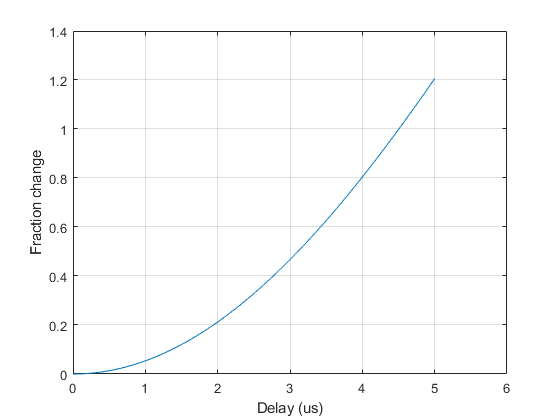

% TODO:

% Soln:  Error is g(t+tau)=g(t)exp(2*pi*delf*tau), so 
%
%   E(t) = |g(t)-g(t)exp(2*pi*delf*tau)|^2 / |g(t)|^2 
%        = 2(1-cos(2*pi*delf*tau)
delf = loppm*fc*1e-6;
tau = linspace(0,5e-6,100);
plot(tau/1e-6, 2*(1-cos(2*pi*delf*tau)));
grid on;
xlabel('Delay (us)');
ylabel('Fraction change');

## Problem 3:  Effect of Delay on a QAM Constellation

In this problem, we will show the effect of fractional delays on a TX constellation.

First, we generate random QPSK symbols.

% TODO:  Generate nb=1024 bits using the randi command.
%   bits = ...
nb = 1024;
bits = randi(2,nb,1)-1;

Modulate the bits using QPSK with the `qammod` command.  Set the `InputType` to '`bit`'.


% TODO:  
%     x = qammod(bits,...);
M = 4;
x = qammod(bits,M,'InputType','bit');

Create a delay object.  You can follow the demo.

% TODO:  Create a delay object
%    dly = dsp.VariableFractionalDelay(...)

dly = dsp.VariableFractionalDelay('InterpolationMethod', 'Farrow');

Shift the symbols `x` by delays `tau` in samples.  Store the delayed samples in `y`.

tau = [10,10.1,10.5];

% TODO:  Shift the symbols x by delays 
%    y = ...
y = dly.step(x,tau);

Plot the received constellations.  Use the subplot command so the constellations for the three delays occur on different windows.  You can skip the first 10 samples since these will be zeros.

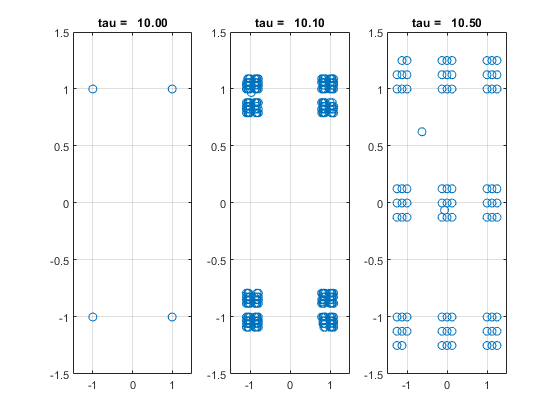

% TODO:  
ntau = length(tau);
i0 = 11;  % First sample to plot
for i = (1:ntau)
    subplot(1,ntau,i);
    plot(real(y(i0:end,i)), imag(y(i0:end,i)), 'o');
    grid on;
    titleStr = sprintf('tau = %7.2f', tau(i));
    title(titleStr);
    axis([-1.5 1.5 -1.5 1.5]);
    
end

## Problem 4:  Computing an OFDM Frequency Response

Consider a system with the following parameters. These paramters are similar to common configuration for a 5G NR system used in the mmWave system

scs = 120e3;  % sub-carrier spacing
nsc = 12*60;  % number of sub-carriers
tsym = 1e-3/14/8;       % OFDM symbol period
nsym = 1000;  % number of symbols to plot

% Channel parameters
fc = 73e9;  % carrier frequency
v = 10;     % RX velocity in m/s
dly = [0,20,50]'*1e-9;   % Delay in sec of the paths
theta = [0,pi/4,pi]';    % Path AoA relative to motion
gaindB = [0,-3,-5]';     % gain of each path in dB

% Random initial phase of the gains
npath = length(dly);
phi = rand(npath,1)*2*pi;

Compute the Doppler shift of each path

% TODO:  Compute the Doppler shift of each path
%   fd = ...
vc = 3e8;
fd = v/vc*fc*cos(theta);


Compute a matrix `H` representing the OFDM channel response where `H(k,n)` is the channel response on symbo numberl `k` and sub-carrier `n`.  

% TODO:  Compute the OFDM channel H(k,n)
%   H = ...
H = zeros(nsym,nsc);
f = scs*(0:nsc-1)';
t = tsym*(0:nsym-1)';

for i = 1:npath
    % Compute the phase.  Note the use of python-like 
    % broadcasting
    phase = 2*pi*fd(i)*t + 2*pi*dly(i)*f' + phi(i);
    
    % Add the path
    H = H + 10^(-0.05*gaindB(i))*exp(1i*phase);
end


Plot the power gain of the channel, 10*log10 `H(k,n)`^2  using the `imagesc` function.  Label the axes across time in ms and frequency in MHz.  You will need to clear the plot with the `subplot(1,1,1)` command.

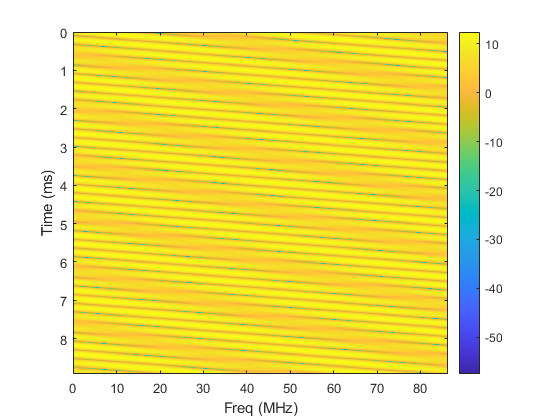

% TODO
subplot(1,1,1);
Hpow = 20*log10(abs(H));
imagesc(f/1e6,t/1e-3,Hpow);
ylabel('Time (ms)');
xlabel('Freq (MHz)');
colorbar();